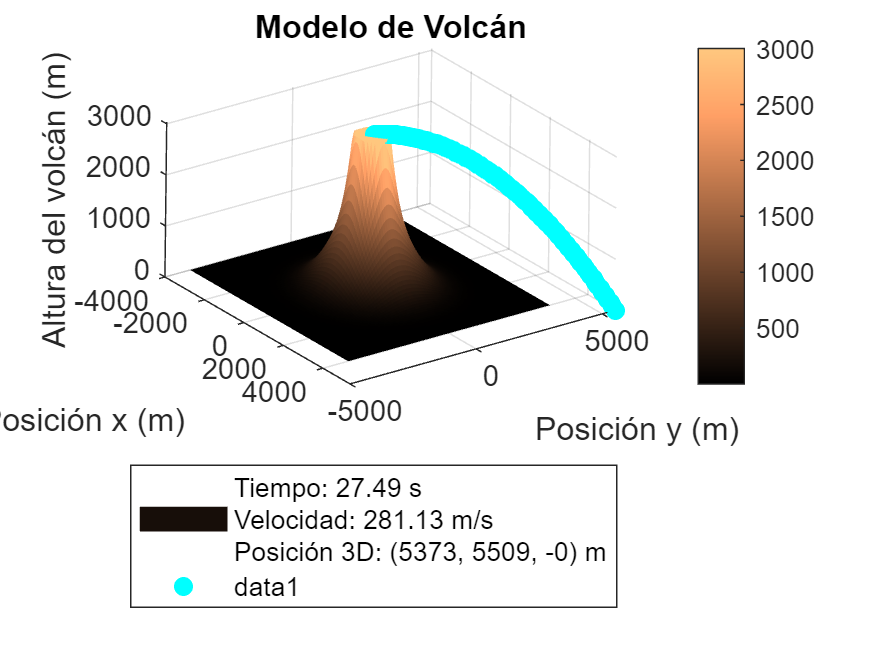

clear
clf

% Definir las dimensiones del volcán
base = 8000; % Ancho del volcán en metros
volcanoLength = 8000; % Longitud del volcán en metros
height = 4000; % Altura del volcán en metros

% Crear una cuadrícula para el volcán
[X, Y] = meshgrid(linspace(-base/2, base/2, 100), linspace(-base/2, base/2, 100));

% Definir la forma del volcán usando esta función
Z = 2000 * exp(-((X.^2 + Y.^2) / (2 * 1000^2))) + height * exp(-((X.^2 + Y.^2) / (2 * 400^2)));

% Limitar los valores para que la altura coincida con la altura del Popocatépetl
Z(Z < 0) = 0;
Z(Z > 3002) = 3002; % Establecer una altura máxima

% Crear la gráfica del volcán
figure;
surf(X, Y, Z, 'EdgeColor', 'none'); % Configura 'EdgeColor' en 'none' para quitar las líneas de malla
xlabel('Posición x (m)');
ylabel('Posición y (m)');
zlabel('Altura del volcán (m)');
title('Modelo de Volcán');
colormap(copper);
colorbar;

% Definir variables para el movimiento del proyectil
g = 9.8;
x0 = 0;
y0 = 0;
z0 = Z(51, 51); % posición inicial para el volcán

% Bucle para generar diferentes datos y llamar a grafica
num_iteraciones = 1; % Número de iteraciones, modifcar papra agregar trayectorias
proyectiles = [];

% Generar una matriz de colores
colores = jet(num_iteraciones);

for iter = 1:num_iteraciones
    % Generar nuevos datos para la función grafica en cada iteración
    [d, V_0, phi, theta, rho_roca, r, A, V, m, Cd, rho_air, b] = generadatos();

    
    % Llamar a la función grafica con los argumentos necesarios
    grafica(V_0, phi, theta,   m,  b, g, x0, y0, z0, Z, colores(iter, :))
    
    info_proyectil = struct();
    info_proyectil.V_0 = V_0;
    info_proyectil.phi = phi;
    info_proyectil.theta = theta;
    info_proyectil.rho_roca = rho_roca;
    info_proyectil.d = d;

    % Calcula y almacena la altura máxima, alcance, velocidad final, etc.
    info_proyectil.altura_maxima = max(Z(:));
    info_proyectil.alcance = max(X(:));
    info_proyectil.velocidad_final = V_0;

    % Agrega la información del proyectil a la matriz de proyectiles
    proyectiles = [proyectiles; info_proyectil];
end


% Crear una estructura con los datos de los proyectiles y cálculos adicionales
proyectiles = struct('Numero_de_Proyectil', num2cell(1:numel(proyectiles)), ...
                     'Velocidad_Inicial_m_s', num2cell([proyectiles.V_0]), ...
                     'Angulo_Horizontal_deg', num2cell([proyectiles.theta] * 180/pi), ...
                     'Angulo_Vertical_deg', num2cell([proyectiles.phi] * 180/pi), ...
                     'Densidad_Roca_kg_m3', num2cell([proyectiles.rho_roca]), ...
                     'Diametro_m', num2cell([proyectiles.d]), ...
                     'Altura_Maxima_m', cell(1, numel(proyectiles)), ...
                     'Tiempo_de_Vuelo_s', cell(1, numel(proyectiles))); % Agregar tiempo de vuelo


% Calcular la distancia parabólica
g = 9.8;  % Asumiendo gravedad constante
for i = 1:numel(proyectiles)
   % Dentro del bucle para cada proyectil
    V_0x = V_0 * sin(phi) * cos(theta);
    V_0y = V_0 * sin(phi) * sin(theta); 
    V_0z = V_0 * cos(phi);
    % Luego, en el cálculo del tiempo de vuelo en la tabla
    t_roots = roots([-0.5 * g, V_0z, z0]);
    t_flight = max(t_roots(t_roots > 0));
    
    % Calcular la altura máxima
    z_max = proyectiles(i).Velocidad_Inicial_m_s^2 * sind(proyectiles(i).Angulo_Vertical_deg)^2 / (2 * g);
    
    proyectiles(i).Altura_Maxima_m = z_max;
    proyectiles(i).Tiempo_de_Vuelo_s = t_flight;

    % Calcular la distancia parabólica
    proyectiles(i).Distancia_Parabolica_m = proyectiles(i).Velocidad_Inicial_m_s * cosd(proyectiles(i).Angulo_Horizontal_deg) * t_flight;
end

% Crear la tabla T a partir de la estructura
T = struct2table(proyectiles);

% Asignar títulos a las columnas con unidades
T.Properties.VariableNames = {'Numero_de_Proyectil', 'Velocidad_Inicial (m/s)', 'Angulo_Horizontal (grados)', 'Angulo_Vertical (grados)', 'Densidad_Roca (kg/m^3)', 'Diametro (m)', 'Altura_Maxima (m)', 'Tiempo_de_Vuelo (s)', 'Distancia_Parabolica (m)'};

% Mostrar la tabla con títulos de columnas y unidades
disp(T);

    Numero_de_Proyectil    Velocidad_Inicial (m/s)    Angulo_Horizontal (grados)    Angulo_Vertical (grados)    Densidad_Roca (kg/m^3)    Diametro (m)    Altura_Maxima (m)    Tiempo_de_Vuelo (s)    Distancia_Parabolica (m)
    ___________________    _______________________    __________________________    ________________________    ______________________    ____________    _________________    ___________________    ________________________

             1                     281.16                       45.715                       84.805                     2244.1               2.6294            4000.1                27.486                    5395.8         



function grafica(V_0, phi, theta,   m,  b, g, x0, y0, z0, Z, color)
    % Resto del código de la función grafica
    % Calcular las componentes de velocidad inicial
    V_0x = V_0 * sin(phi) * cos(theta);
    V_0y = V_0 * sin(phi) * sin(theta);
    V_0z = V_0 * cos(phi);

    % Calcular tiempo de vuelo
    t_roots = roots([-0.5 * g, V_0z, z0]);
    t_flight = max(t_roots(t_roots > 0));

    % Tiempo y posición del vuelo
    t = linspace(0, t_flight, 100);

    x = x0 + V_0x * t;
    y = y0 + V_0y * t;
    z = zeros(size(t));

    % Gráfico de la trayectoria
    hold on;

    grid on;

    % Inicializar variables para distancia total recorrida y altura máxima
    distancia_total = 0;
    altura_maxima = z0 - min(Z(:)); % Altura máxima relativa al volcán

    for i = 1:length(t)
        if t(i) > 0
            % Calcular la aceleración en la dirección z debido a la fuerza de arrastre
            a_drag_z = -(b * V_0z * abs(V_0z)) / m;

            % Calcular la aceleración en la dirección x e y (horizontal) debido a la fuerza de arrastre
            a_drag_x = -(b * V_0x * abs(V_0x)) / m;
            a_drag_y = -(b * V_0y * abs(V_0y)) / m;

            % Actualizar las velocidades en las tres direcciones (x, y, z)
            V_0x = V_0x + a_drag_x;
            V_0y = V_0y + a_drag_y;
            V_0z = V_0z + a_drag_z;

            % Actualizar las posiciones en las tres direcciones
            x(i) = x0 + V_0x * t(i);
            y(i) = y0 + V_0y * t(i);
            z(i) = z0 + V_0z * t(i) - 0.5 * g * t(i)^2;



            % Actualizar la altura máxima relativa al terreno o volcán
            lgd = sprintf('Tiempo: %.2f s\nVelocidad: %.2f m/s\nPosición 3D: (%.0f, %.0f, %.0f) m', t(i), V_i, x(i), y(i), z(i));
            legend(lgd, 'Location', 'southoutside');
            plot3(x(i), y(i), z(i), 'o', 'MarkerFaceColor', color, 'MarkerEdgeColor', color);
            % ...

            % Verificar si el proyectil ha llegado a z=0 o se volvió negativo
            if z(i) <= 0
                z(i) = 0; % Establecer z en 0 para detener la trayectoria
                break; % Salir del bucle
            end
        end

        % Calcular la velocidad en cada iteración
        V_i = sqrt(V_0x^2 + V_0y^2 + V_0z^2);

        % Actualizar la leyenda con la velocidad

        camorbit(1, 0);
        drawnow;
        pause(0.00001); % Controlar la velocidad de la animación
    end
end

function [d, V_0, phi, theta, rho_roca, r, A, V, m, Cd, rho_air, b] = generadatos()
    % Código para generar valores aleatorios y cálculos
    d = 1 + (3 - 1) * rand(); % Diámetro entre 0.1 y 3 metros
    V_0 = 100 + (300 - 100) * rand(); % Velocidad entre 100 y 300 m/s
    
    % Generar ángulos aleatorios en coordenadas esféricas
    theta = 2 * pi * rand(); % Ángulo azimutal (horizontal)
    phi = 0.524 + (pi/2 - 0.524) * rand();% Ángulo polar (vertical) entre 30 grados   y pi/2, cuando pi es 0 va hacia arriba, cuando es pi/2 va hacia el ecuador, osea en sentido recto,  asi limitamos la altura en lo que se podria decir entre 30 y 90 grados
    % Calcular las componentes de velocidad inicial
    gamma = atan2(sin(phi), cos(phi) * cos(theta));

    % Asegurarse de que gamma esté en el rango de [0, π]
    if gamma < 0
        gamma = gamma + (pi/2);
    end

  
    rho_roca = 600 + (3200 - 600) * rand(); % Densidad entre 300 y 2300 kg por metro^3
    
    r = d/2; % metros
    A = pi * r^2;
    V = 4/3 * pi * r^3;
    m = V * rho_roca;
    
    % Calcular resistencia del aire
    Cd = 0.47; % Coeficiente de arrastre, 0. es recomendable para una esfera
    rho_air = 1.225; % Densidad del aire, valor estándar
    b = 0.5 * rho_air * gamma * A * Cd / m;
end
